# 4. Training Networks

load satData.mat % load the image and class labels

### Peek into the data

Note the dimensions of the data.

categories(YTrain) % View the class labels

ans = 6×1 cell 배열
    {'barren land'}
    {'building'   }
    {'grassland'  }
    {'road'       }
    {'trees'      }
    {'water'      }


size(XTrain) % View the dimensions of the training set of image data

ans =           28          28           4        3000


## Create a Network from Layers

### Create the CNN Layers

Create a column vector of 7 layers named `layers`, with the layers in the order shown below.

`imageInputLayer``(``inputSize``)`

`convolution2dLayer``(``filterSize``,``numFilters``)`

`reluLayer``()`

`maxPooling2dLayer``(``poolSize``)`

`fullyConnectedLayer``(``numClasses``)`

`softmaxLayer``()`

`classificationLayer``()`

Use the following information to choose the inputs for the layers:

- Each image is size 28-by-28-by-4.

- The convolution layer should have a 20 filters of size 3-by-3.

- The pooling layer should have a pool size of 3-by-3.

- There are six classes.

layers = [imageInputLayer([28,28,4]);convolution2dLayer([3,3],20);reluLayer();maxPooling2dLayer([3,3]);...
    fullyConnectedLayer(6);softmaxLayer();classificationLayer()]

layers =   다음 계층을 포함한 7×1 Layer 배열:

     1   ''   영상 입력          28×28×4 영상 (정규화: 'zerocenter')
     2   ''   2차원 컨벌루션      20개 3×3 컨벌루션(스트라이드: [1  1], 채우기: [0  0  0  0])
     3   ''   ReLU             ReLU
     4   ''   2차원 최댓값 풀링   3×3 최댓값 풀링 (스트라이드: [1  1], 채우기: [0  0  0  0])
     5   ''   완전 연결          6 완전 연결 계층
     6   ''   소프트맥스         소프트맥스
     7   ''   분류 출력          crossentropyex

## Train the Network with Different Training Options

### Training Options

Create training options named `options`. 

- Use the algorithm `"sgdm"`,`"adam(sgdm(모멘텀) + rmsprop(히스토리))"` and `"rmsprop(히스토리. 과거가 안좋으면 뒤에도 안좋다)". 뭐 sgdm = adam 비슷하거나 sgdm이 더 논리적이라, sgdm이 더 높거나.`

- Set the maximum number of epochs to 5 to 100 -> 5 ~ 100

- Set the minibatch size to 200

- Set the initial learning rate to 0.0001 and 0.001 (If you set 0.001, you will see `NaN` of Mini-batch Loss in the training-progress plot. How can you fix this without decreasing the initial learning rate? Use Gradient Clipping with `GradientThreshold` option.)

- 초기 학습률을 0.0001 및 0.001로 설정합니다(0.001로 설정하면 훈련 진행 플롯에 NaN of Mini-batch Loss가 표시됩니다. 초기 학습률을 줄이지 않고 이 문제를 어떻게 해결할 수 있습니까? GradientThreshold 옵션과 함께 Gradient Clipping을 사용하세요. )

- Plot the training progress

options = trainingOptions("sgdm","MaxEpochs",5,"MiniBatchSize",128,"InitialLearnRate",0.001)

(MiniBatchSize, 일반적으로 엣지사이즈라고 불림)배치사이즈 -> 1000개를 200개의 배치사이즈로 한다? 그럼 5개의 배치가 나온다. 즉 하나의 에폭에 (5개 사용 -> 미니배치사이즈 200)

하나의 배치로 러너블파라미터를 업데이트(Weigth, 바이어스). 업데이트가 한번 이루어질때마다, 데이터의 갯수/MinBatchSize =  (23.XX 이면 23번만 돌아간다.)1에폭 당 이터레이션(배치의 갯수)이라고 한다. 1에폭 당 이터레이션 * 전체 에폭 = > 이터레이션이다.

InitialLearnRate(골짜기를 걸어가는데 얼마나 큰 걸음으로 걸어갈 것인가. 스케쥴링(Learningrate Scedule이 에폭이 한 5회? 돌면 늘린다던지 스케쥴이 가능)이 가능하기에 Initial이고, 에폭을 반복함에 따라 1/10을 해줌으로 보폭을 줄여나간다.)에 따라 들쑥 날쑥함 -> 안정적이진 않음. 시작점이 랜덤하게 시작하기 때문에 최적점을 찾아가는데 중간에 멈추기 때문. 이것에 직접적인 영향을 주는 것 = MaxEpochs. 즉 5회 반복으로는 부족하다.

즉 들쭉날쭉한 것은 학습 되는 과정에서 끝나게 되었기 때문. 그렇기 때문에 추가적인 학습이 필요하고 많은 반복을 해줘야한다. 시작점은 랜덤함.

다 다른 에러값을 더한게 최소가 되게끔 하는게 목표.

보폭이 떨어진 순간부터 학습이 다시 시작되기 때문에 이미 큰 손실을 봤다. -> 알고리즘 적절히 사용. 관성을 유지하는 방향으로 가게끔.

- "sgdm" -> 확률적 경사하강법 -> 기울기가 감소(gradient decent)하는 방향으로 간다. (Low Loss value) -> 알고리즘. 주변을 돌아보고 기울기가 낮은 것을 채우고 -> 알고리즘을 돌림.(얼마나 멀리 보느냐? LearnRate) LearnRate가 크면 초반에 Loss는 쭉쭉 떨어지지만, 보폭이 크니까 나중에는 들쭉날쭉한 형태를 보여줌. 옵션(모멘텀)

- "backpropagation" -> Loss 값을 기준으로 나머지를 계속 튜닝한다. 결과를 알고 있고, 예측한 값에 대해 풀이 과정을 끼워 맞추기. (Gradient가 낮아지는 방향으로. 방향은 정해져있음)

- Gradient Clipping with `GradientThreshold` option. : Gradient가 또 너무 낮아지는 방향으로 가면 들쑥날쑥하니까 모멘텀(관성)을 둬야함. 너무 낮아지면 일정한 값을 넣어버림. (학습시간이 너무 길어 -> 러닝레이트를 작게 하고 싶을때 사용)

Gradient(기울기)는 신경망 학습 중 가중치(weight)와 편향(bias)을 조정하기 위한 중요한 개념입니다. 신경망은 손실 함수(loss function)를 최소화하기 위해 가중치와 편향을 조절하는데, 이때 Gradient를 사용합니다. 2 -> 2이상의 기울기는 그냥 2를 넣어라. (너무 와일드하게 움직일 경우) 그냥 정해줌.

- LearnRateSchedule, piecewise, LearnRateDropPeriod, LearnRateDropFactor(기본 값 0.1)

% opts = trainingOptions("sgdm","MaxEpochs",50,"InitialLearnRate",0.001,"Plots","training-progress","GradientThreshold",2)
opts = trainingOptions("sgdm","MaxEpochs",50,"InitialLearnRate",0.0001,"Plots","training-progress",...
    "LearnRateSchedule","piecewise","LearnRateDropPeriod",1,"LearnRateDropFactor",0.1)

opts =   TrainingOptionsSGDM - 속성 있음:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-04
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 1
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 50
                   MiniBatchSize: 128
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
                       OutputFcn: []
          

### Train the Network

net = trainNetwork(XTrain,YTrain,layers,opts)

단일 CPU에서 훈련합니다.
입력 데이터의 정규화를 초기화하는 중입니다.
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　Ｅｐｏｃｈ　　｜　　반복　횟수　　｜　　　　경과　시간　　　　　｜　　미니　배치　정확도　　｜　　미니　배치　손실　　｜　　기본　학습률　　｜
｜　　　　　　　　　｜　　　　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　｜　　　　　　　　　　　　｜　　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　　１　｜　　　　　　　１　｜　　　　　００：００：０３　｜　　　　　　２５．００％　｜　　　　６３．４３８３　｜　１．００００ｅ－０４　｜
｜　　　　　　　３　｜　　　　　　５０　｜　　　　　００：００：０５　｜　　　　　　７５．００％　｜　　　　２４．２５２８　｜　１．００００ｅ－０６　｜
｜　　　　　　　３　｜　　　　　　６１　｜　　　　　００：００：０５　｜　　　　　　７８．１２％　｜　　　　３０．２４８８　｜　１．００００ｅ－０６　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
훈련 완료: 수동으로 중지되었습니다.


net =   SeriesNetwork - 속성 있음:

         Layers: [7×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


### Classify and Evaluate the Network

 % Prediction by the network
Test_Pred = classify(net, XTest)

Test_Pred = 600×1 categorical 배열
     barren land 
     road 
     building 
     building 
     building 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     building 
     barren land 
     barren land 
     barren land 
     grassland 
     building 
     barren land 
     grassland 
     grassland 
     road 
     barren land 
     barren land 
     building 
     barren land 
     barren land 
     building 
     building 
     barren land 


Test_GT = YTest

Test_GT = 600×1 categorical 배열
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 


Test_Acc = nnz(Test_Pred == Test_GT)/numel(Test_GT)

Test_Acc = 0.8050

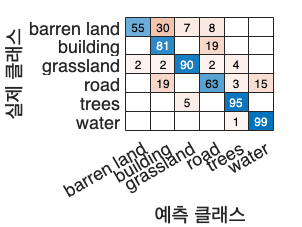

valData = 1×2 cell 배열
    {28×28×4×600 uint8}    {600×1 categorical}


 % Visualization in a confusion matrix
confusionchart(Test_GT, Test_Pred)

## Validation Data Set 검증 데이터

To prevent overfitting, you can use a validation data set. If the validation accuracy is consistently lower than the training accuracy, you can stop the training.

검증 데이터 세트는 훈련 중에 네트워크를 평가하는 데 사용되는 별도의 데이터 분할입니다.

- 훈련 데이터 : 훈련 중에 가중치를 업데이트하는 데 사용

- 검증 데이터 : 훈련 중에 성능을 평가하는 데 사용

- 테스트 데이터 : 훈련 후에 성능을 평가하는 데 사용

과적합(일반화가 되지 않아 항상 방지해야함.)을 방지하려면 검증 데이터 세트를 사용할 수 있습니다. 검증 정확도가 훈련 정확도보다 지속적으로 낮은 경우 훈련을 중지할 수 있습니다. >> 공부? 우리가 딱히 할건 없음.

검증 데이터는 네트워크가 과적합되었는지 감지하는 데 유용합니다. 훈련 손실이 감소하더라도 검증 손실이 증가하면 네트워크가 훈련에 대한 세부 정보를 학습하고 있으므로 훈련을 중지해야 합니다. 새 이미지와 관련이 없는 데이터입니다.

valData = {XVal, YVal} %train이 valds 항상 높다. 벨리데이션은 훈련 용으로 있지 않다. 어래이는 안됨.

valData = 1×2 cell 배열
    {28×28×4×600 uint8}    {600×1 categorical}


options = trainingOptions("sgdm","MaxEpochs",100,"MiniBatchSize",200,...
    "InitialLearnRate",0.0001,...
    "ValidationData",valData,"ValidationFrequency",10) %10번 업데이트하고 한번 예측

options =   TrainingOptionsSGDM - 속성 있음:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-04
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 100
                   MiniBatchSize: 200
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: {[28×28×4×600 uint8]  [600×1 categorical]}
             ValidationFrequency: 10
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
       

landnet = trainNetwork(XTrain,YTrain,layers,options);

단일 CPU에서 훈련합니다.
입력 데이터의 정규화를 초기화하는 중입니다.
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　Ｅｐｏｃｈ　　｜　　반복　횟수　　｜　　　　경과　시간　　　　　｜　　미니　배치　정확도　　｜　　검증　정확도　　｜　　미니　배치　손실　　｜　　검증　손실　　｜　　기본　학습률　　｜
｜　　　　　　　　　｜　　　　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　｜　　　　　　　　　　｜　　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　　１　｜　　　　　　　１　｜　　　　　００：００：００　｜　　　　　　１８．００％　｜　　　３７．３３％　｜　　　　２５．８１９９　｜　４３．５８８３　｜　１．００００ｅ－０４　｜
｜　　　　　　　１　｜　　　　　　１０　｜　　　　　００：００：００　｜　　　　　　７６．００％　｜　　　７６．１７％　｜　　　　２２．６４４１　｜　２１．７７４１　｜　１．００００ｅ－０４　｜
｜　　　　　　　２　｜　　　　　　２０　｜　　　　　００：００：０１　｜　　　　　　７３．５０％　｜　　　８７．３３％　｜　　　　　９．８１０２　｜　　３．３６２５　｜　１．００００ｅ－０４　｜
｜　　　　　　　２　｜　　　　　　３０　｜　　　　　００：００：０１　｜　　　　　　８６．００％　｜　　　８４．８３％　｜　　　　　３．９７３９　｜　　６．０５３７　｜　１．００００ｅ－０４　｜
｜　　　　　　　３　｜　　　　　　４０　｜　　　　　００：００：０２　｜　　　　　　８３．５０％　｜　　　９２．３３％　｜　　　　　６．０１８６　｜　　２．２３８５　｜　１．００００ｅ－０４　｜
｜　　　　　　　４　｜　　　　　　５０　｜　　　　　００：００：０２　｜　　　　　　９３．５０％　｜　　　８８．３３％　｜　　　　　１．６８９６　｜　　４．５８３１　｜　

testPrediction = classify(landnet,XTest)

testPrediction = 600×1 categorical 배열
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     grassland 
     barren land 
     barren land 
     grassland 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 
     barren land 


testAcc = nnz(testPrediction == YTest) / numel(testPrediction)

testAcc = 0.9450

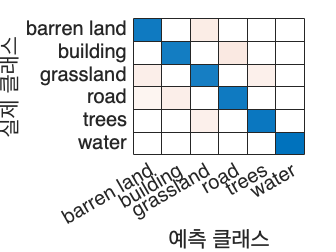

confusionchart(YTest,testPrediction) % Visualization in a confusion matrix